# Network Analysis

## Prepare the Environment

clc;
clearvars;
close all;

## Load Adj Matrices and Tables

% Weighted adjecency matrix by year
w_adj_matrix_by_year = load('./Adjacency Matrix/w_adjacency_matrix_by_year.mat');
w_adj_matrix_by_year = w_adj_matrix_by_year.w_adj_matrix_by_year;

% Migration table
migrationT = load('./Tables/migrationT.mat');
migrationT = migrationT.migrationT;

% Economic Indicator table
economyT = load('./Tables/economyT.mat');
economyT = economyT.economyT;

## Network Creation

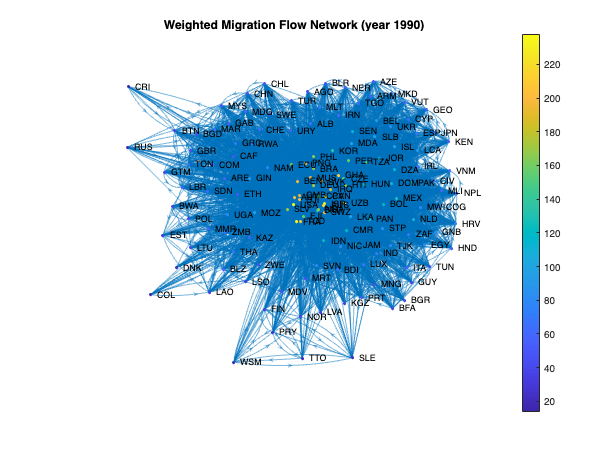

codes = unique(migrationT.Code);
years = unique(migrationT.Year);

% Arrays of networks (one for each year)
graphs = cell(1, length(years));

for i = 1:length(years)
    G = digraph(w_adj_matrix_by_year(:, :, i), codes);
    graphs{i} = G;
end

% Plot weighted matrix network (year 1990)
figure
LWidths = 5*graphs{1}.Edges.Weight/max(graphs{1}.Edges.Weight);
plot(graphs{1}, 'Layout', 'force', 'NodeCData', graphs{1}.indegree+graphs{1}.outdegree, 'NodeLabel', codes, 'LineWidth', LWidths)
title('Weighted Migration Flow Network (year 1990)')
colorbar
axis off


clearvars("codes", "years", "LWidths", "G", "i")

## Degree and Strength Measures

% Number of years taken in consideration
n_years = size(w_adj_matrix_by_year, 3);
n_countries = size(w_adj_matrix_by_year, 1);

% Degree matrix initialization
inDeg = zeros(n_years, n_countries);
outDeg = zeros(n_years, n_countries);
Deg = zeros(n_years, n_countries);

% Strength matrix initialization
inStr = zeros(n_years, n_countries);
outStr = zeros(n_years, n_countries);
Str = zeros(n_years, n_countries);

for i = 1:n_years   
    G = graphs{i};

    % Degree computation
    inDeg(i, :) = G.centrality("indegree");           % Input degrees
    outDeg(i, :) = G.centrality("outdegree");         % Output degrees
    Deg(i, :) = inDeg(i, :) + outDeg(i, :);           % Total degrees

    % Strength computation
    inStr(i, :) = G.centrality("indegree", 'Importance', G.Edges.Weight);   % Input strenghts
    outStr(i, :) = G.centrality("outdegree", 'Importance', G.Edges.Weight); % Output strenghts
    Str(i, :) = inStr(i, :) + outStr(i, :);                                 % Total strenghts
end   

clearvars("n_countries", "n_years", "i", "G")

### Plot Degree and Strength

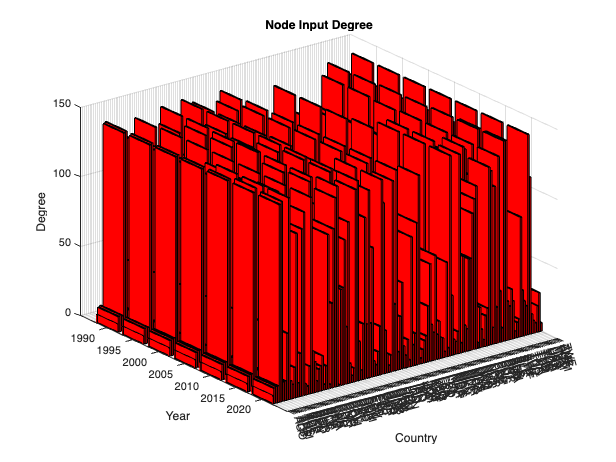

% Plot Degree properties
codes = categorical(unique(migrationT.Code)');
years = unique(migrationT.Year);

figure
bar3(Deg, 'blue')
title('Node Degree')
xticks(1:length(codes))
xticklabels(codes)
yticks(1:length(years))
yticklabels(years)
xlabel('Country')
ylabel('Year')
zlabel('Degree')
axis normal
grid on

figure
bar3(inDeg, 'red')
title('Node Input Degree')
xticks(1:length(codes))
xticklabels(codes)
yticks(1:length(years))
yticklabels(years)
xlabel('Country')
ylabel('Year')
zlabel('Degree')
axis normal
grid on

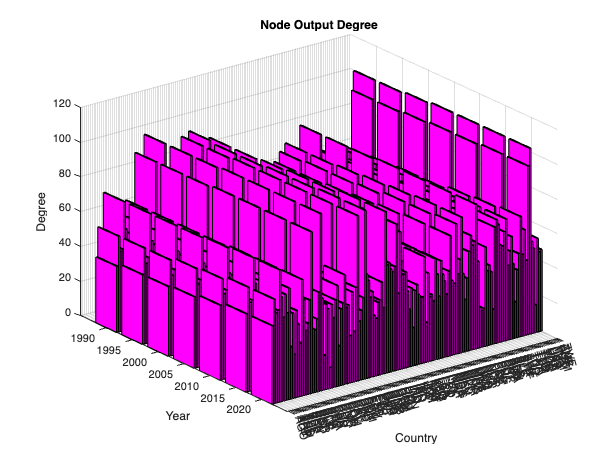


figure
bar3(outDeg, 'magenta')
title('Node Output Degree')
xticks(1:length(codes))
xticklabels(codes)
yticks(1:length(years))
yticklabels(years)
xlabel('Country')
ylabel('Year')
zlabel('Degree')
axis normal
grid on

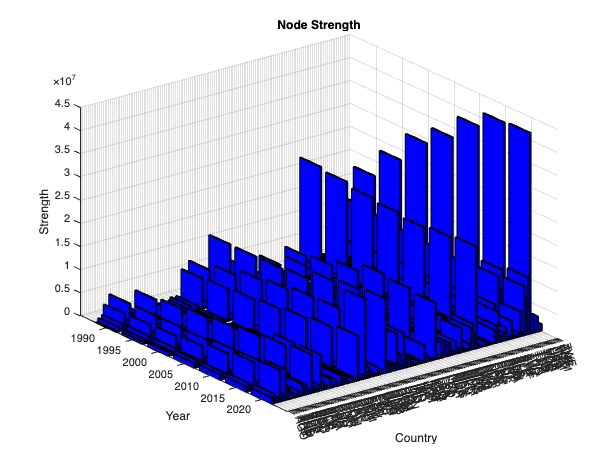


% Plot Strength properties
figure
bar3(Str, 'blue')
title('Node Strength')
xticks(1:length(codes))
xticklabels(codes)
yticks(1:length(years))
yticklabels(years)
xlabel('Country')
ylabel('Year')
zlabel('Strength')
axis normal
grid on

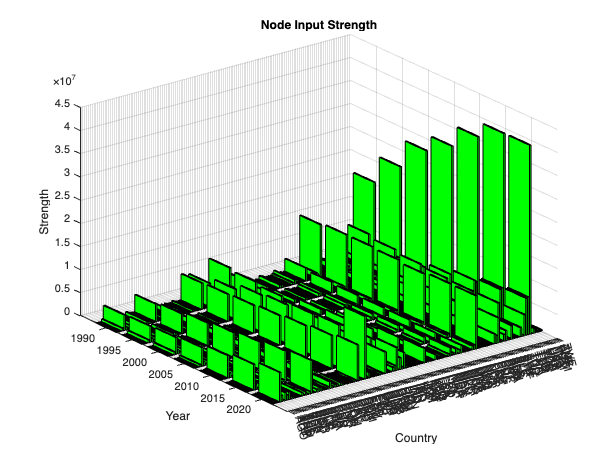


figure
bar3(inStr, 'green')
title('Node Input Strength')
xticks(1:length(codes))
xticklabels(codes)
yticks(1:length(years))
yticklabels(years)
xlabel('Country')
ylabel('Year')
zlabel('Strength')
axis normal
grid on

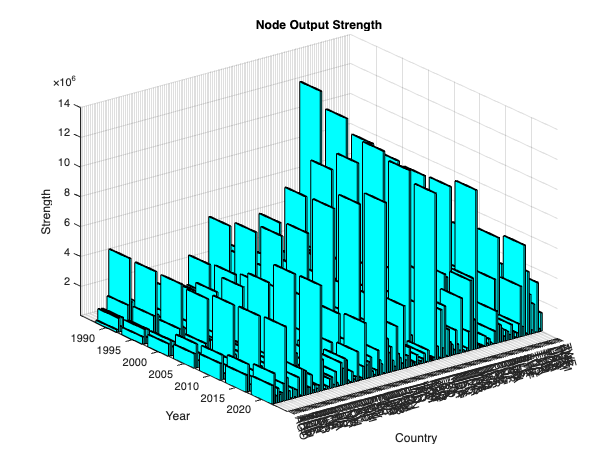


figure
bar3(outStr, 'cyan')
title('Node Output Strength')
xticks(1:length(codes))
xticklabels(codes)
yticks(1:length(years))
yticklabels(years)
xlabel('Country')
ylabel('Year')
zlabel('Strength')
axis normal
grid on


clearvars("codes", "years")

### Most popular countries

countries = unique(migrationT.Country)';
years = unique(migrationT.Year);

% Top 5 countries havin more connections
[~, deg_rankIdx] = sort(Deg, 2, "descend");
disp('Top 5 countries according to Degree measure:')

Top 5 countries according to Degree measure:


disp(array2table(countries(deg_rankIdx(:, 1:5)), ...
    "RowNames", string(years), "VariableNames", ["Rank1", "Rank2", "Rank3", "Rank4", "Rank5"], ...
    "DimensionNames", ["Year", "Rank"]))

                 Rank1               Rank2           Rank3       Rank4          Rank5     
            ________________    ________________    ________    _______    _______________

    1990    "France"            "United Kingdom"    "Canada"    "Italy"    "United States"
    1995    "France"            "United Kingdom"    "Canada"    "Italy"    "United States"
    2000    "France"            "United Kingdom"    "Canada"    "Italy"    "United States"
    2005    "United Kingdom"    "France"            "Canada"    "Italy"    "United States"
    2010    "United Kingdom"    "France"            "Canada"    "Italy"    "United States"
    2015    "United Kingdom"    "France"            "Canada"    "Italy"    "United States"


% Top 5 countries having more incoming edges
[~, indeg_rankIdx] = sort(inDeg, 2, "descend");
disp('Top 5 countries having more incoming edges:')

Top 5 countries having more incoming edges:


disp(array2table(countries(indeg_rankIdx(:, 1:5)), ...
    "RowNames", string(years), "VariableNames", ["Rank1", "Rank2", "Rank3", "Rank4", "Rank5"], ...
    "DimensionNames", ["Year", "Rank"]))

              Rank1           Rank2               Rank3              Rank4            Rank5    
            _________    ________________    ________________    _____________    _____________

    1990    "France"     "United Kingdom"    "Austria"           "Denmark"        "Italy"      
    1995    "France"     "Italy"             "United Kingdom"    "Austria"        "Denmark"    
    2000    "France"     "Italy"             "United Kingdom"    "Austria"        "Sweden"     
    2005    "France"     "Italy"             "United Kingdom"    "Austria"        "Czechia"    
    2010    "Belgium"    "France"            "Italy"             "Netherlands"    "Norway"     
    2015    "Austria"    "Belgium"           "France"  


% Top 5 countries having more outgoing edges
[~, outdeg_rankIdx] = sort(outDeg, 2, "descend");
disp('Top 5 countries having more outgoing edges:')

Top 5 countries having more outgoing edges:


disp(array2table(countries(outdeg_rankIdx(:, 1:5)), ...
    "RowNames", string(years), "VariableNames", ["Rank1", "Rank2", "Rank3", "Rank4", "Rank5"], ...
    "DimensionNames", ["Year", "Rank"]))

                 Rank1          Rank2       Rank3           Rank4               Rank5      
            _______________    _______    _________    ________________    ________________

    1990    "United States"    "China"    "Germany"    "France"            "United Kingdom"
    1995    "United States"    "China"    "Germany"    "France"            "United Kingdom"
    2000    "United States"    "China"    "France"     "Germany"           "United Kingdom"
    2005    "United States"    "China"    "Germany"    "United Kingdom"    "France"        
    2010    "United States"    "China"    "Germany"    "United Kingdom"    "France"        
    2015    "United States"    "China"    "Germany"    "United Kingdom"    "France"


% Top 5 countries receiving/sending migrants
[~, str_rankIdx] = sort(Str, 2, "descend");
disp('Top 5 countries according to Strength measure:')

Top 5 countries according to Strength measure:


disp(array2table(countries(str_rankIdx(:, 1:5)), ...
    "RowNames", string(years), "VariableNames", ["Rank1", "Rank2", "Rank3", "Rank4", "Rank5"], ...
    "DimensionNames", ["Year", "Rank"]))

                 Rank1              Rank2           Rank3        Rank4           Rank5      
            _______________    _______________    _________    _________    ________________

    1990    "Russia"           "United States"    "India"      "Ukraine"    "Germany"       
    1995    "United States"    "Russia"           "India"      "Ukraine"    "Germany"       
    2000    "United States"    "Russia"           "India"      "Germany"    "Ukraine"       
    2005    "United States"    "Russia"           "India"      "Germany"    "Mexico"        
    2010    "United States"    "Russia"           "India"      "Mexico"     "Germany"       
    2015    "United States"    "Russia"           "India"      "Mexico"     


% Top 5 countries receiving immigrants
[~, instr_rankIdx] = sort(inStr, 2, "descend");
disp('Top 5 most popular migration destinations:')

Top 5 most popular migration destinations:


disp(array2table(countries(instr_rankIdx(:, 1:5)), ...
    "RowNames", string(years), "VariableNames", ["Rank1", "Rank2", "Rank3", "Rank4", "Rank5"], ...
    "DimensionNames", ["Year", "Rank"]))

                 Rank1           Rank2        Rank3           Rank4                  Rank5         
            _______________    _________    _________    ________________    ______________________

    1990    "United States"    "Russia"     "India"      "Ukraine"           "France"              
    1995    "United States"    "Russia"     "India"      "Germany"           "France"              
    2000    "United States"    "Russia"     "Germany"    "India"             "France"              
    2005    "United States"    "Russia"     "Germany"    "France"            "India"               
    2010    "United States"    "Russia"     "Germany"    "France"            "United Arab Emirates"
    2015    "United States"


% Top 5 countries sending migrants
[~, outstr_rankIdx] = sort(outStr, 2, "descend");
disp('Top 5 countries sources of immigrants:')

Top 5 countries sources of immigrants:


disp(array2table(countries(outstr_rankIdx(:, 1:5)), ...
    "RowNames", string(years), "VariableNames", ["Rank1", "Rank2", "Rank3", "Rank4", "Rank5"], ...
    "DimensionNames", ["Year", "Rank"]))

             Rank1        Rank2        Rank3         Rank4           Rank5    
            ________    _________    _________    ____________    ____________

    1990    "Russia"    "Ukraine"    "India"      "Bangladesh"    "Mexico"    
    1995    "Russia"    "Mexico"     "Ukraine"    "India"         "Bangladesh"
    2000    "Russia"    "Mexico"     "India"      "Ukraine"       "Bangladesh"
    2005    "Mexico"    "Russia"     "India"      "Ukraine"       "China"     
    2010    "Mexico"    "Russia"     "India"      "China"         "Ukraine"   
    2015    "Mexico"    "India"      "Russia"     "China"         "Ukraine"   
    2020    "India"     "Mexico"     "Russia"     "China"         "Ukraine"   


% Countries with many incoming connections, but a low in-strenght
disp('Countries with many incoming connections, but a low in-strenght:')

Countries with many incoming connections, but a low in-strenght:


disp(setdiff(countries(indeg_rankIdx(:, 1:5)), countries(instr_rankIdx(:, 1:5))))

    "Austria"
    "Belgium"
    "Czechia"
    "Denmark"
    "Italy"
    "Netherlands"
    "Norway"
    "Sweden"




% Countries with many outgoing connections, but a low out-strenght
disp('Countries with many outgoing connections, but a low out-strenght:')

Countries with many outgoing connections, but a low out-strenght:


disp(setdiff(countries(outdeg_rankIdx(:, 1:5)), countries(outstr_rankIdx(:, 1:5))))

    "France"
    "Germany"
    "United Kingdom"
    "United States"




clearvars("countries", "years")

## Centrality Measures

n_years = size(w_adj_matrix_by_year, 3);
n_countries = size(w_adj_matrix_by_year, 1);

% Matrix initializations
btw_cen = zeros(n_years, n_countries);
inClose_cen = zeros(n_years, n_countries);
outClose_cen = zeros(n_years, n_countries);
eigen_cen = zeros(n_years, n_countries);
page_cen = zeros(n_years, n_countries);
hubs = zeros(n_years, n_countries);
authorities = zeros(n_years, n_countries);

for i = 1:n_years
    G = graphs{i};
    % Betweenness Centrality    
    % Identify countries that serve as key intermediaries in migration flows. 
    % High betweenness countries act as “bridges” between regions. 
    % This can help you find which countries play a pivotal role in routing migration
    btw_cen(i, :) = G.centrality('betweenness', 'Cost', G.Edges.Weight);    

    % Closeness Centrality
    % In-closeness centrality measures how easily a country can receive 
    % migrants from other countries
    inClose_cen(i, :) = G.centrality('incloseness', 'Cost', G.Edges.Weight);
    % Out-closeness centrality measures how easily a country can send 
    % migrants to other countries
    outClose_cen(i, :) = G.centrality('outcloseness', 'Cost', G.Edges.Weight);

    % Eigenvector Centrality   
    % It will help you identify countries that have high "influence" in terms 
    % of being destinations or origins in the migration network
    adj = w_adj_matrix_by_year(:, :, i);
    [v, d] = eig(adj);
    [~, idx] = max(diag(d));
    largest_eig = v(:, idx);
    centr = abs(largest_eig) / sum(abs(largest_eig));
    eigen_cen(i, :) = centr;

    % Page rank
    % It will help you identify countries that have high "influence" in terms 
    % of being destinations or origins in the migration network, accounting 
    % for the direction and flow of migration, while preventing bias towards 
    % countries with disproportionately high outflows or inflows
    page_cen(i, :) = G.centrality('pagerank', 'Importance', G.Edges.Weight);

    % Hubs
    % Countries that are significant sources of migration
    hubs(i, :) = G.centrality('hubs', 'Importance', G.Edges.Weight);

    % Authorities
    % Countries that are major destinations for migration
    authorities(i, :) = G.centrality('authorities', 'Importance', G.Edges.Weight);
end

clearvars("G", "centr", "largest_eig", "idx", "v", "d", "adj", "n_years", "n_countries", ...
    "i")

### Clustering Coefficients

% Initialize cluster matrices
[numCountries, ~, numYears] = size(w_adj_matrix_by_year);
inClustering = zeros(numYears, numCountries);
outClustering = zeros(numYears, numCountries);
overallClustering = zeros(numYears, numCountries);

for year = 1:numYears
    % Extract adjacency matrix for the current year
    A = w_adj_matrix_by_year(:,:,year);
    
    % Ensure A is non-negative (if weights include negatives, adjust accordingly)
    A(A < 0) = 0;
    
    % Compute for each node
    for i = 1:numCountries
        % Find neighbors (in and out)
        inNeighbors = find(A(:,i) > 0); % Nodes pointing to i
        outNeighbors = find(A(i,:) > 0); % Nodes pointed by i
        
        % In-Clustering Coefficient
        k_in = inDeg(year, i); % In-degree
        if k_in > 1
            inTriangles = 0;
            for j = inNeighbors'
                for k = inNeighbors'
                    if j ~= k
                        inTriangles = inTriangles + (A(j,i) * A(i,k) * A(k,j))^(1/3);
                    end
                end
            end
            inClustering(year, i) = inTriangles / (k_in * (k_in - 1));
        else
            inClustering(year, i) = 0;
        end
        
        % Out-Clustering Coefficient
        k_out = outDeg(year, i); % Out-degree
        if k_out > 1
            outTriangles = 0;
            for j = outNeighbors
                for k = outNeighbors
                    if j ~= k
                        outTriangles = outTriangles + (A(i,j) * A(j,k) * A(k,i))^(1/3);
                    end
                end
            end
            outClustering(year, i) = outTriangles / (k_out * (k_out - 1));
        else
            outClustering(year, i) = 0;
        end
        
        % Overall Clustering Coefficient
        if (k_in > 1 || k_out > 1)
            overallTriangles = 0;
            for j = 1:numCountries
                for k = 1:numCountries
                    if j ~= k && i ~= j && i ~= k
                        overallTriangles = overallTriangles + ...
                            (A(i,j) * A(j,k) * A(k,i))^(1/3);
                    end
                end
            end
            totalPairs = (k_in + k_out) * (k_in + k_out - 1);
            overallClustering(year, i) = overallTriangles / totalPairs;
        else
            overallClustering(year, i) = 0;
        end
    end
end

### Centrality Table

inDegCol = reshape(inDeg, size(migrationT, 1), 1);
outDegCol = reshape(outDeg, size(migrationT, 1), 1);
degCol = reshape(Deg, size(migrationT, 1), 1);
inStrCol = reshape(inStr, size(migrationT, 1), 1);
outStrCol = reshape(outStr, size(migrationT, 1), 1);
strCol = reshape(Str, size(migrationT, 1), 1);
btwCol = reshape(btw_cen, size(migrationT, 1), 1);
inCloseCol = reshape(inClose_cen, size(migrationT, 1), 1);
outCloseCol = reshape(outClose_cen, size(migrationT, 1), 1);
eigenCol = reshape(eigen_cen, size(migrationT, 1), 1);
pageRankCol = reshape(page_cen, size(migrationT, 1), 1);
hubsCol = reshape(hubs, size(migrationT, 1), 1);
authoritiesCol = reshape(authorities, size(migrationT, 1), 1);
inClusteringCol = reshape(inClustering, size(migrationT, 1), 1);
outClusteringCol = reshape(outClustering, size(migrationT, 1), 1);
overallClusteringCol = reshape(overallClustering, size(migrationT, 1), 1);

centralityT = table(inDegCol, outDegCol, inStrCol, outStrCol, btwCol, ...
    inCloseCol, outCloseCol, eigenCol, pageRankCol, hubsCol, authoritiesCol, ...
    inClusteringCol, outClusteringCol, 'VariableNames', ...
    ["In_Degree", "Out_Degree", "In_Strength", "Out_Strength", ...
    "Betweenness", "In_Closeness", "Out_Closeness", "Eigenvector", ...
    "Page_Rank", "Hubs", "Authorities", "In_Clustering", "Out_Clustering"]);
centralityT = [migrationT(:, 1:3), centralityT]

centralityT = 1022×16 table
     Country     Code     Year    In_Degree    Out_Degree    In_Strength    Out_Strength    Betweenness    In_Closeness    Out_Closeness    Eigenvector    Page_Rank       Hubs       Authorities    In_Clustering    Out_Clustering
    _________    _____    ____    _________    __________    ___________    ____________    ___________    ____________    _____________    ___________    _________    __________    ___________    _____________    <s


clearvars("btwCol", "inCloseCol", "outCloseCol", "eigenCol", ...
    "pageRankCol", "hubsCol", "authoritiesCol")

### Centrality Distributions

centralities = centralityT.Properties.VariableNames(8:end);

for i = 1:length(centralities)
    centrality = centralities{i};

    figure;
    histogram2(centralityT.(centrality), centralityT.Year, 'FaceColor', 'flat')
    title([centrality, ' Distribution'])
    colorbar;
end

clearvars("centralities", "i", "centrality")

### Country Centrality Distributions

centralities = centralityT.Properties.VariableNames(8:end);

for i = 1:length(centralities)
    centrality = centralities{i};
    % Pivot table
    P = pivot(centralityT,Columns="Country",Rows="Year",DataVariable=centrality, RowLabelPlacement="rownames");
    Pmatrix = table2array(P);

    % Plot centrality distribution
    figure;
    b = bar3(Pmatrix);
    xticks(1:length(centralityT.Country));
    xticklabels(unique(centralityT.Code))
    xlabel('Country')
    yticks(1:length(centralityT.Year));
    yticklabels(unique(centralityT.Year))
    ylabel('Year')    
    zlabel(centrality);

    % Adjust the color mapping to reflect the Z-values
    for k = 1:length(b)
        zdata = get(b(k), 'ZData');  % Get Z data
        set(b(k), 'CData', zdata);   % Set CData to Z data to color according to Z values
    end
    
    colormap turbo;  % Color gradient for better visualization
    shading interp;  % Smooth the color transitions
    colorbar;
    axis normal;
    title([centrality, ' Distribution by Country'])
end

clearvars("centralities", "i", "centrality", "P", "Pmatrix", "b", "k", "zdata")

### Country Centrality Distributions (surface variant)

years = unique(migrationT.Year);
codes = unique(migrationT.Code);
n_years = length(years);
n_countries = length(codes);

centralities = centralityT.Properties.VariableNames(4:end);

for i = 1:length(centralities)
    centrality = centralities{i};

    % Build 2D grid of coordinates 
    [time_mesh, country_mesh] = meshgrid(1:n_years, 1:n_countries);
    
    % Pivot table
    P = pivot(centralityT,Columns="Country",Rows="Year",DataVariable=centrality, RowLabelPlacement="rownames");
    Pmatrix = table2array(P);

    % Plot centrality distribution
    figure;
    surf(country_mesh', time_mesh', Pmatrix);
    yticks(1:n_years)
    yticklabels(years)
    xticks(1:n_countries)
    xticklabels(codes)
    ylabel('Years');
    xlabel('Country');
    zlabel([centrality, ' Centrality']);
    
    colormap jet;  % Color gradient for better visualization
    shading interp;  % Smooth the color transitions
    colorbar;
        
    grid on;   
    title([centrality, ' Distribution by Country'], 'Interpreter', 'none')
end

clearvars("centralities", "i", "centrality", "P", "Pmatrix", "years", "codes", ...
    "n_countries", "n_years", "time_mesh", "country_mesh")

### Most meaningful countries by measure

countries = unique(migrationT.Country)';
centralities = centralityT.Properties.VariableNames(8:end);

for i = 1:length(centralities)
    centrality = centralities{i};
    
    % Pivot table
    P = pivot(centralityT,Columns="Country",Rows="Year",DataVariable=centrality, RowLabelPlacement="rownames");
    Pmatrix = table2array(P);

    % Top 5 countries
    [rankValue, rankIdx] = sort(Pmatrix, 2, "descend");
    disp(['Top 5 countries according to ', centrality, ':'])
    disp([countries(rankIdx(:, 1:5)), num2str(rankValue(:, 1:5))])
    disp('Overall list of top 5 countries across years')
    disp(unique(countries(rankIdx(:, 1:5))))

    % Bottom 5 countries    
    disp(['Bottom 5 countries according to ', centrality, ':'])
    disp([countries(rankIdx(:, end-4:end)), num2str(rankValue(:, end-4:end))])
    disp('Overall list of bottom 5 countries across years')
    disp(unique(countries(rankIdx(:, end-4:end))))
end

% Show relevant countries according to eigenvector centrality but not to page rank
P = pivot(centralityT,Columns="Country",Rows="Year",DataVariable="Eigenvector", RowLabelPlacement="rownames");
Pmatrix = table2array(P);
[~, rankIdx] = sort(Pmatrix, 2, "descend");
eigenCountries = countries(rankIdx(:, 1:5));

P = pivot(centralityT,Columns="Country",Rows="Year",DataVariable="Page_Rank", RowLabelPlacement="rownames");
Pmatrix = table2array(P);
[~, rankIdx] = sort(Pmatrix, 2, "descend");
pageCountries = countries(rankIdx(:, 1:5));

disp('Countries at the top 5 for Eigenvector centrality but not for Page Rank:')
disp(setdiff(eigenCountries, pageCountries))

clearvars("countries", "centralities", "i", "centrality", "P", "Pmatrix", ...
    "rankIdx", "eigenCountries", "pageCountries")

### Trends over Time

countries = unique(centralityT.Country);
centralities = centralityT.Properties.VariableNames(8:end);

% Initialize p-value and estimate matrices
trend_p_values = zeros(length(centralities), length(countries));
trend_estimates = zeros(length(centralities), length(countries));

for i = 1:length(countries)
    country = countries(i);
    idx = centralityT.Country == country;
    countryCentrality = centralityT(idx, :);
    for j = 1:length(centralities)
        centrality = centralities{j};
        mdl = fitlm(countryCentrality, 'PredictorVars', 'Year', 'ResponseVar', centrality);
        trend_p_values(j, i) = mdl.Coefficients.pValue(2); 
        trend_estimates(j, i) = mdl.Coefficients.Estimate(2);
    end
end

% Analyze p-values to determine countries with significant trends
significant_trends = trend_p_values < 0.05;
significant_positive_trends = trend_p_values < 0.05 & trend_estimates > 0;
significant_negative_trends = trend_p_values < 0.05 & trend_estimates < 0;

commTrendCentralityCountries = countries(significant_trends(:, 1)); % Initialize countries with trend in all centralities
allTrendCentralityCountries = countries(significant_trends(:, 1));  % Initialize countries with trend in at least one centrality
for i = 1:length(centralities)
    centrality = centralities{i};

    % Relevant countries
    significantCountries = countries(significant_trends(i, :));
    significantPositiveCountries = countries(significant_positive_trends(i, :));
    significantNegativeCountries = countries(significant_negative_trends(i, :));

    % Countries showin a trend for each centrality
    disp(['Countries showing a trend over time in ', centrality])    
    if isempty(significantCountries)
        disp('No country showing a trend')
    else
        disp(significantCountries)
    end    

    disp(['Countries showing a positive trend over time in ', centrality])    
    if isempty(significantPositiveCountries)
        disp('No country showing a trend')
    else
        disp(significantPositiveCountries)
    end    

    disp(['Countries showing a negative trend over time in ', centrality])    
    if isempty(significantNegativeCountries)
        disp('No country showing a trend')
    else
        disp(significantNegativeCountries)
    end    

    % Countries showing a trend in all  and at least one of centralities
    if i ~= 1 && i ~= length(centralities)
        commTrendCentralityCountries = intersect(commTrendCentralityCountries, countries(significant_trends(i, :)));
        allTrendCentralityCountries = union(countries(significant_trends(:, i)), allTrendCentralityCountries);
    else
        commTrendCentralityCountries = intersect(commTrendCentralityCountries, countries(significant_trends(i, :)));
        allTrendCentralityCountries = union(countries(significant_trends(:, i)), allTrendCentralityCountries);
        
        disp('Countries showing a trend over time in all centrality measures:')
        disp(commTrendCentralityCountries)

        disp('Countries showing a trend over time in at least one centrality measure:')
        disp(allTrendCentralityCountries)
    end       
end

clearvars("countries", "trend_p_values", "significant_trends", "mdl", "centralities", ...
    "i", "country", "commTrendCentralityCountries", "allTrendCentralityCountries", ...
    "idx", "countryCentrality", "j", "centrality", "significantCountries", "significantNegativeCountries", ...
    "significantPositiveCountries")

### Significant Shifts across 3 Decades

countries = unique(migrationT.Country);
years = unique(migrationT.Year);
centralities = centralityT.Properties.VariableNames(8:end);

periodStep = 2;
numPeriods = (length(years) - 1) / periodStep;
% Initialize average period matrix
avgPeriod = zeros(numPeriods, length(countries));

for i = 1:length(centralities)
    centrality = centralities{i};
    % Pivot table
    P = pivot(centralityT,Columns="Country",Rows="Year",DataVariable=centrality, RowLabelPlacement="rownames");
    Pmatrix = table2array(P);
    for j = 1:2:length(years)-2
        startYear = years(j);
        endYear = years(j+2);

        period = Pmatrix(j:j+2, :);
        idx = (j + 1) / periodStep;
        avgPeriod(idx, :) = mean(period, 1);

        if j ~= 1
            % Paired t-test (to see if there’s a significant difference)
            [~, p_values] = ttest(avgPeriod(idx, :), avgPeriod(idx-1, :));
            significant_countries = p_values < 0.05;
            disp(['Countries showing significant changes in ', ...
                centrality, ' between period ', ...
                num2str(years(j-periodStep)), '-', num2str(startYear), ...
                ' and period ', num2str(startYear), '-', num2str(endYear)])
            if ~isempty(countries(significant_countries))
                countries(significant_countries)
            else
                disp('None')
            end
        end        
    end    
end

clearvars("countries", "years", "centralities", "i", "j", "idx", "periodStep", ...
    "numPeriods", "p_values", "significant_countries", "avgPeriod", "centrality", ...
    "P", "Pmatrix", "startYear", "endYear", "period")

### Continent-Level Clustering Analysis

continents = unique(economyT.Continent);
years = unique(economyT.Year);
countries = unique(economyT.Country);
continentClustering = zeros(length(years), length(continents));

% Compute overall continent clustering
for i = 1:length(continents)
    continent = continents(i);
    idx_continent = economyT.Continent == continent;    
    cont_countries = unique(economyT.Country(idx_continent));
    idx_countries = ismember(cont_countries, countries);    
    continentClustering(:, i) = mean(overallClustering(:, idx_countries), 2);
end

% Display continent clustering
figure;
bar(continentClustering);
xticks(1:length(years));
xticklabels(years);
xlabel('Year');
legend(continents, 'Location', 'eastoutside');
title('Clustering by Continent');

clearvars("continents", "years", "countries", "i", "continent", "idx_continent", ...
    "cont_countries", "idx_countries")

### Correlation with Economic Indicators

indicators = economyT.Properties.VariableNames(4:end-1);
centralities = centralityT.Properties.VariableNames(8:end);

% Initialize correlation matrix
corrMatrix = zeros(length(indicators), length(centralities));

for i = 1:length(indicators)
    indicator = indicators{i};
    figure;
    t = tiledlayout(length(centralities), 1);
    for j = 1:length(centralities)
        centrality = centralities{j};
        corrMatrix(i, j) = corr(centralityT{:, centrality}, economyT{:, indicator});

        % Display correlation
        nexttile;
        scatter(economyT.(indicator), centralityT.(centrality), 50)
        title(centrality)
    end
    title(t, [indicator, ' - ', centrality, ' relationship'], 'Interpreter', 'none');
end

% Plot correlation coefficients
figure;
heatmap(centralities, indicators, corrMatrix, 'Interpreter', 'none');

clearvars("indicators", "indicator", "i", "j", "centralities", ...
    "corrMatrix", "t")

### Measures Correlation

centralities = centralityT.Properties.VariableNames(8:end);

rho = corr(centralityT{:, 4:end});
% Plot correlation coefficients
figure;
heatmap(centralities, centralities, rho, 'Interpreter', 'none');
corrplot(centralityT(:, 4:end));

clearvars("rho", "centralities")

### Save centrality measures

save('./Centrality/betweenness.mat', "btw_cen");
save('./Centrality/in_closeness.mat', "inClose_cen");
save('./Centrality/out_closeness.mat', "outClose_cen");
save('./Centrality/eigenvector.mat', "eigen_cen");
save('./Centrality/page_rank.mat', "page_cen");
save('./Centrality/hubs.mat', "hubs");
save('./Centrality/authorities.mat', "authorities");
save('./Tables/centralityT.mat', "centralityT");

## Assortativity Measure

assortativity_degree = zeros(1, size(w_adj_matrix_by_year, 3));

% Assortativity based on weights
for t = 1:size(w_adj_matrix_by_year, 3)
    assortativity_degree(t) = assortativity_wei(w_adj_matrix_by_year(:, :, t), 1);
end
disp('Assortativity by year:')
disp(assortativity_degree)

## Modularity and Community Detection

### Modularity Measures (undirected, directed, weighted)

num_years = size(w_adj_matrix_by_year, 3);
years = unique(migrationT.Year);

% Initialize arrays to store modularity values
Q_undirected = zeros(1, num_years);
Q_directed = zeros(1, num_years);
Q_weighted_directed = zeros(1, num_years);

for t = 1:num_years
    % Extract the adjacency matrix for the specific year
    A = squeeze(w_adj_matrix_by_year(:, :, t));
    
    % Undirected, Unweighted Network
    A_undirected = (A + A') / 2;  % Symmetrize
    A_undirected(A_undirected > 0) = 1;  % Binarize
    [~, Q_undirected(t)] = community_louvain(A_undirected);

    % Directed, Unweighted Network
    A_directed = A;  % Binarize without symmetrizing
    A_directed(A_directed > 0) = 1;
    [~, Q_directed(t)] = community_louvain(A_directed);

    %% Directed, Weighted Network
    A_weighted = A / max(A(:));  % Normalize weights
    [~, Q_weighted_directed(t)] = community_louvain(A_weighted);
end

% Display modularity values for each year
disp('Modularity over years (Undirected, Directed, Weighted Directed):');
modularityT = array2table([years, Q_undirected', Q_directed', Q_weighted_directed'], ...
      'VariableNames', {'Year', 'Undirected', 'Directed', 'Weighted_Directed'})

clearvars("num_years", "years", "Q_undirected", "Q_directed", "Q_weighted_directed", ...
    "t", "A", "A_undirected", "A_directed", "A_weighted")

### Display results

years = modularityT.Year;

% Plot modularity over time
figure;
plot(years, modularityT.Undirected, '-o', 'LineWidth', 2, 'DisplayName', 'Undirected');
hold on;
plot(years, modularityT.Directed, '-o', 'LineWidth', 2, 'DisplayName', 'Directed');
plot(years, modularityT.Weighted_Directed, '-o', 'LineWidth', 2, 'DisplayName', 'Weighted Directed');
xlabel('Year');
ylabel('Modularity (Q)');
title('Modularity Over Time');
legend;
grid on;

clearvars("years")

### Modularity - Economy Correlation

years = unique(migrationT.Year);
indicators = economyT.Properties.VariableNames(4:end-1);

% Initialize matrices
economicIndicatorMean = zeros(length(years), length(indicators));

% Extract mean of economic indicators
for i = 1:length(years)
    for j = 1:length(indicators)
        indicator = indicators{j};
        idx = economyT.Year == years(i);        
        economicIndicatorMean(i, j) = mean(economyT.(indicator)(idx));
    end    
end

% Economic Indicator Means table 
economicIndicatorMeanT = array2table(economicIndicatorMean, 'RowNames', string(years), 'VariableNames', indicators);
% Scale Economic Indicator Means for better comprehension
scaledEconomicIndicatorMeanT = normalize(economicIndicatorMeanT, "range");

figure;
t = tiledlayout(length(indicators), 1, "TileSpacing", "loose", "Padding", "loose");
% Plot Modularity vs Economic Indicator
for i = 1:length(indicators)
    indicator = indicators{i};
    
    nexttile;
    plot(years, modularityT.Undirected, '-o', 'LineWidth', 2, 'Color', 'b', 'DisplayName', 'Undirected Modularity');
    hold on;
    plot(years, modularityT.Directed, '-o', 'LineWidth', 2, 'Color', "#D95319", 'DisplayName', 'Directed Modularity');    
    plot(years, modularityT.Weighted_Directed, '-o', 'LineWidth', 2, 'Color', 'y', 'DisplayName', 'Weighted Modularity');        

    yyaxis right;
    plot(years, scaledEconomicIndicatorMeanT.(indicator), '-x', 'LineWidth', 2, 'Color', 'r', 'DisplayName', ['Mean ', indicator]);            
    ylabel(indicator);    
    hold off;

    grid on;                    
    title(['Modularity vs ', indicator], 'Interpreter', 'none');             
end
xlabel(t, 'Year'); 
lgd = legend('Economic Indicator', 'Undirected Modularity', 'Directed Modularity', 'Weighted Modularity');
lgd.Location = "southoutside";

clearvars("years", "economicIndicatorMean", "indicators", "i", "j", "idx", "t", "lgd")

#### Weighted Modularity - Economy Indicators Correlation Measure

indicators = economyT.Properties.VariableNames(4:end-1);
numMod = size(modularityT, 2) - 1;

% Initialize Correlation matrix
corrModIndicator = zeros(numMod, length(indicators));

% Compute correlation
for i = 1:numMod
    for j = 1:length(indicators)
        corrModIndicator(i, j) = corr(modularityT{:, i+1}, economicIndicatorMeanT{:, j});
    end
end

% Plot correlation coefficients
figure;
yvalues = modularityT.Properties.VariableNames(2:end);
heatmap(indicators, yvalues, corrModIndicator);

## Community Analysis

### Identify Communities

codes = unique(migrationT.Code);
years = unique(migrationT.Year);

% Initialize matrix to store community memberships over years
community_memberships = zeros(length(years), length(codes));

for t = 1:length(years)
    % Extract adjacency matrix for the specific year
    A = squeeze(w_adj_matrix_by_year(:, :, t));
    
    % Symmetrize and binarize the adjacency matrix for community detection
    A_undirected = (A + A') / 2;
    A_undirected(A_undirected > 0) = 1;
    
    % Run Louvain community detection
    [Ci_undirected, ~] = community_louvain(A_undirected);
    
    % Store community memberships for each year
    community_memberships(t, :) = Ci_undirected;
end

% Plot community membership changes of countries
figure;
imagesc(community_memberships);
colorbar;
xticks(1:length(codes));
xticklabels(codes);
yticks(1:length(years));
yticklabels(years);
xlabel('Country');
ylabel('Year');
title('Community Memberships Over Time');

clearvars("countries", "years", "t", "A", "A_undirected", "Ci_undirected")

### Community Stability

num_countries = size(w_adj_matrix_by_year, 2);
num_years = size(w_adj_matrix_by_year, 3);
codes = unique(migrationT.Code);
countries = unique(migrationT.Country);

% Community Stability Analysis
stability_count = sum(diff(community_memberships) == 0, 1);  % Number of stable transitions across years
stability_percentage = (stability_count / (num_years - 1)) * 100;  % Convert to percentage

% Identify countries with stable and shifting memberships
threshold = 80;
stable_countries = find(stability_percentage >= threshold);
shifting_countries = find(stability_percentage < threshold);

% Plot Stability Analysis
figure;
bar(stability_percentage);
xticks(1:num_countries);
xticklabels(codes);
xlabel('Countries');
ylabel('Stability Percentage');
title('Community Membership Stability Across Years');
grid on;
hold on;
yline(threshold, 'r--', 'Threshold');

% Highlight stable and shifting countries
disp('Stable countries (above threshold):');
disp(countries(stable_countries));

disp('Shifting countries (below threshold):');
disp(countries(shifting_countries));

clearvars("num_countries", "num_years", "countries", "stability_count", "stability_percentage", ...
    "threshold", "codes")

### Community size

num_countries = size(w_adj_matrix_by_year, 1);  
num_years = size(w_adj_matrix_by_year, 3);  
years = unique(migrationT.Year);

% Initialize matrix to store community sizes for each year
max_communities = max(max(community_memberships));  % Max possible number of communities
community_sizes = zeros(num_years, max_communities);

% Calculate Community Sizes
for t = 1:num_years
    communities_t = community_memberships(t, :);
    for c = 1:max_communities
        community_sizes(t, c) = sum(communities_t == c);  % Size of community c in year t
    end
end

% Plot community sizes over time
figure;
plot(community_sizes, 'LineWidth', 2);
xticks(1:num_years);
xticklabels(years);
xlabel('Year');
ylabel('Community Size');
title('Community Sizes Over Time');
legend(arrayfun(@(x) sprintf('Community %d', x), 1:max_communities, 'UniformOutput', false));
grid on;

clearvars("num_countries", "num_years", "years", "max_communities", "t", "communities_t", ...
    "c")

### Largest and most stable communities

countries = unique(migrationT.Country);

% Largest community across most years
[largest_community_size, largest_community_idx] = max(sum(community_sizes));
communities = find(sum(community_sizes) == largest_community_size);
if isscalar(communities)
    country_idx = any(community_memberships(:, :) == communities);
    largest_community_countries = countries(country_idx);
    disp(["The largest community accross most years is community number ", num2str(largest_community_idx)])
    disp(["This community comprises (across years)", num2str(length(largest_community_countries)), " countries:"])
    disp(largest_community_countries)
else
    disp(["The largest community accross most years are communities number ", num2str(communities)])
    for i = 1:length(communities)
        disp(["Community ", num2str(communities(i)), " comprises (across years) ", num2str(length(largest_community_countries)), " countries:"])
        country_idx = any(community_memberships(:, :) == communities(i));
        largest_community_countries = countries(country_idx);
        disp(largest_community_countries)
    end
end

% Most stable community across most years
counter = zeros(1, size(community_sizes, 2));
for i = 2:size(community_sizes, 1)
    upper = community_sizes(i-1, :) + community_sizes(i-1, :) * 0.1;
    lower = community_sizes(i-1, :) - community_sizes(i-1, :) * 0.1;
    idx = community_sizes(i, :) <= upper & community_sizes(i-1, :) >= lower;
    counter(idx) = counter(idx) + 1;
end
most_stable = max(counter);
communities = find(counter == most_stable);
disp("The most stable communities across years are communities:")
disp(communities)

clearvars("countries", "largest_community_size", "largest_community_idx", "communities", ...
    "country_idx", "largest_community_countries", "i", "counter", "upper", "lower", ...
    "idx", "most_stable")

### Community Clustering Coefficients

years = unique(migrationT.Year);
num_communities = max(max(community_memberships));
communityClustering = zeros(length(years), num_communities);

for i = 1:num_communities
    idx = community_memberships(:, :) == i;
    clustering = overallClustering(idx);
    communityClustering(:, i) = sum(clustering);
end

% Display Community Clustering
figure;
bar(communityClustering);
xticks(1:length(years));
xticklabels(years);
xlabel('Year');
legend(string(1:num_communities), 'Location', 'eastoutside');
title('Clustering by Community');

clearvars("years", "num_communities", "i", "idx", "clustering")

### Community-Continent Relationship

continents = reshape(economyT.Continent, [size(community_memberships, 1), size(community_memberships, 2)]);
continentNames = unique(continents);
countryNames = reshape(economyT.Country, [size(community_memberships, 1), size(community_memberships, 2)]);
years = unique(economyT.Year);
num_communities = max(max(community_memberships));

% Initialize table and matrices
communityCountries = strings(size(community_memberships, 1), size(community_memberships, 2));
communityContinents = strings(size(community_memberships, 1), size(community_memberships, 2));
communityContinentCount = zeros(length(years), length(continentNames), num_communities);
countT = table('Size', [length(years), length(continentNames)], ...
    'VariableNames', continentNames, ...
    'VariableTypes', ["int32", "int32", "int32", "int32", "int32", "int32"], ...
    'RowNames', string(years));

for i = 1:num_communities
    
    % Identify countries and respective continents for the community
    communityCountriesIdx = community_memberships(:, :) == i;
    communityCountries(communityCountriesIdx) = countryNames(communityCountriesIdx);
    communityContinents(communityCountriesIdx) = continents(communityCountriesIdx);

    % Count the number of countries appearing in each continent
    for j = 1:length(continentNames)
        name = continentNames(j);
        idx = communityContinents(:, :) == name;
        communityContinentCount(:, j, i) = sum(idx, 2);
    end        
   
    % Temporary table
    countT{:, :} = communityContinentCount(:, :, i);

    for k = 1:length(years)
        disp(["Countries belonging to community ", num2str(i), "in year ", num2str(years(k)), ":"])
        disp(rmmissing(unique(communityCountries(k, :))))
        disp(["Number of times continents appear in community ", num2str(i)])
        disp(countT)
    end

    % Plot Community Continent Evolution
    figure;
    plot(years, communityContinentCount(:, 1, i), 'Color', "r", 'LineWidth', 2.5)
    hold on
    plot(years, communityContinentCount(:, 2, i), 'Color', "g", 'LineWidth', 2.5)
    plot(years, communityContinentCount(:, 3, i), 'Color', "b", 'LineWidth', 2.5)
    plot(years, communityContinentCount(:, 4, i), 'Color', "m", 'LineWidth', 2.5)
    plot(years, communityContinentCount(:, 5, i), 'Color', "#D95319", 'LineWidth', 2.5)
    plot(years, communityContinentCount(:, 6, i), 'Color', "k", 'LineWidth', 2.5)
    hold off
    legend(continentNames, 'Location', 'eastoutside');
    title(["Community ", num2str(i), " -Continent Evolution"])
end

clearvars("continents", "continentNames", "countryNames", "years", "num_communities", ...
    "countT", "i", "communityCountriesIdx", "j", "name", "idx", "k")